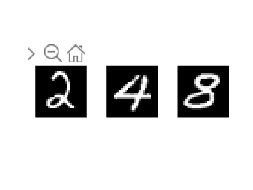


% To visualise one image , you can simply try: 
im = reshape(digit2(:,1), [ 28, 28]); % the first image of the digit 311 
subplot(1,3,1);
imshow(im,[]); 
im = reshape(digit4(:,1), [ 28, 28]); % the first image of the digit 316 
subplot(1,3,2);
imshow(im,[]);
im = reshape(digit8(:,1), [ 28, 28]); % the first image of the digit 319 
subplot(1,3,3);
imshow(im,[]);

%加载数据
load digits_369.mat;
%合并数据
data = [digit2,digit4,digit8];
%对数据进行zscore正则化
%data = zscore(data);

%其他数据
load digits.mat
data = [digit2,digit4,digit8,digit1,digit5,digit7,digit3,digit6,digit9];

对数据打标签

% 假设你有3个类别的图像，每个类别有1500个图像
num_classes = 3;
num_images_per_class = 1500;
% 创建一个空的数组来存储ground truth
groundTruth = zeros(num_classes * num_images_per_class, 1);
% 为每个类别的图像分配一个标签
for i = 1:num_classes
    groundTruth((i-1)*num_images_per_class+1 : i*num_images_per_class) = i;
end
%独热编码
groundTruthOneHot = full(ind2vec(groundTruth'));

现在是ovo

% 假设你有2个类别的图像，每个类别分别有1500和3000个图像
num_classes = 2;
num_images_per_class = [1500,3000];

% 创建一个空的数组来存储ground truth
% 需要预先计算总图像数
total_images = sum(num_images_per_class);
groundTruth2 = zeros(total_images, 1);

% 为每个类别的图像分配一个标签
for i = 1:num_classes
    start_index = sum(num_images_per_class(1:i-1)) + 1;
    end_index = sum(num_images_per_class(1:i));
    groundTruth2(start_index:end_index) = i;
end

groundTruthOneHot_ovo= full(ind2vec(groundTruth2'));
